% analysis damage
clear
clc

load Data.mat



% remove inter
figure

% cal damage level C
subplot(2, 2, 1)

data = squeeze(abs(C(:, 1, :) - C(:, 2, :))) ./ squeeze(abs(C(:, 1, :)));

bar(mean(data, 2))
hold on
errorbar(mean(data, 2), std(data, [], 2), 'LineStyle', 'none')
xticklabels({'HAN', 'LAN', 'DFN'})
ylabel('Damage level C')
title('Remove inter-regional connections')
ylim([0 0.9])

[H, P(1), CI, STATS] = ttest2(data(1, :), data(2, :));
[H, P(2), CI, STATS] = ttest2(data(1, :), data(3, :));
[H, P(3), CI, STATS] = ttest2(data(3, :), data(2, :));
P = mafdr(P, "BHFDR", 'true')

P = 	1.0e+-92 *

    0.0000    0.0000    0.1279



subplot(2, 2, 2)
r = corrcoef(activity_inter(1, :), data(1, :));
h = plot_scatter(data(1, :), activity_inter(1, :));
xlim([0.4 0.9])
ylabel('Averaged inter-regional activity level')
xlabel('damage level C')
[H, P, CI, STATS] = ttest2(activity_inter(1, :), data(1, :));
text(0.65, 0.85, {['r = ', num2str(r(1, 2))], ['p = ', num2str(P)]}, "FontSize", 14)


% cal damage level L
subplot(2, 2, 3)

data = squeeze(abs(L(:, 1, :) - L(:, 2, :))) ./ squeeze(abs(L(:, 1, :)));

bar(mean(data, 2))
hold on
errorbar(mean(data, 2), std(data, [], 2), 'LineStyle', 'none')
xticklabels({'HAN', 'LAN', 'DFN'})
ylabel('Damage level L')
title('Remove inter-regional connections')
ylim([0 0.4])

[H, P(1), CI, STATS] = ttest2(data(1, :), data(2, :));
[H, P(2), CI, STATS] = ttest2(data(1, :), data(3, :));
[H, P(3), CI, STATS] = ttest2(data(3, :), data(2, :));
P = mafdr(P, "BHFDR", 'true')

P = 1×3 single 行向量
	1.0e+-30 *

    0.1980         0         0


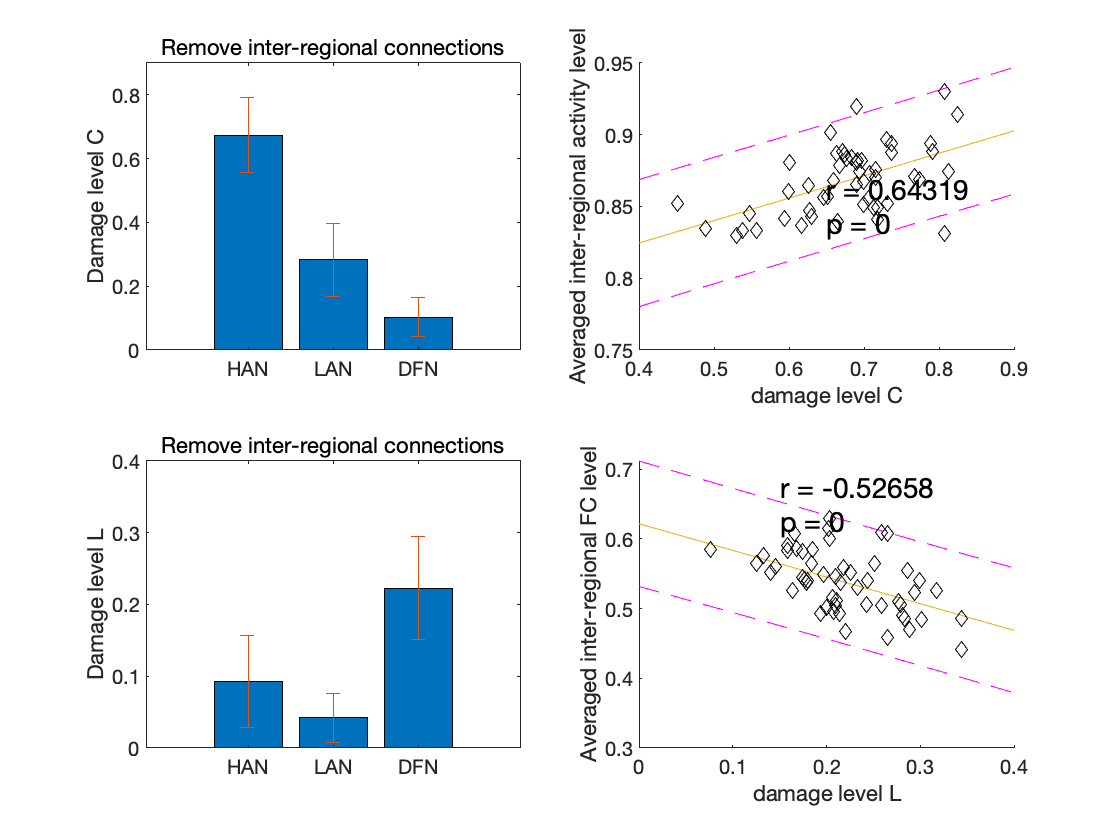


subplot(2, 2, 4)
r = corrcoef(activity_inter(3, :), data(3, :));
h = plot_scatter(data(3, :), activity_inter(3, :));
xlim([0 0.4])
ylabel('Averaged inter-regional FC level')
xlabel('damage level L')
[H, P, CI, STATS] = ttest2(activity_inter(3, :), data(3, :));
text(0.15, 0.65, {['r = ', num2str(r(1, 2))], ['p = ', num2str(P)]}, "FontSize", 14)

% remove intra

figure

% cal damage level C
subplot(2, 2, 1)

data = squeeze(abs(C(:, 1, :) - C(:, 3, :))) ./ squeeze(abs(C(:, 1, :)));

bar(mean(data, 2))
hold on
errorbar(mean(data, 2), std(data, [], 2), 'LineStyle', 'none')
xticklabels({'HAN', 'LAN', 'DFN'})
ylabel('Damage level C')
title('Remove intra-regional connections')
ylim([0 0.9])

[H, P(1), CI, STATS] = ttest2(data(1, :), data(2, :));
[H, P(2), CI, STATS] = ttest2(data(1, :), data(3, :));
[H, P(3), CI, STATS] = ttest2(data(3, :), data(2, :));
P = mafdr(P, "BHFDR", 'true')

P = 1×3 single 行向量
    0.0422         0         0



subplot(2, 2, 2)
r = corrcoef(1 - activity_inter(3, :), data(3, :));
h = plot_scatter(data(3, :), 1 - activity_inter(3, :));
xlim([0.4 0.9])
ylabel('Averaged inter-regional FC level')
xlabel('damage level C')
[H, P, CI, STATS] = ttest2(1 - activity_inter(3, :), data(3, :));
text(0.55, 0.65, {['r = ', num2str(r(1, 2))], ['p = ', num2str(P)]}, "FontSize", 14)


% cal damage level L
subplot(2, 2, 3)

data = squeeze(abs(L(:, 1, :) - L(:, 3, :))) ./ squeeze(abs(L(:, 1, :)));
bar(mean(data, 2))
hold on
errorbar(mean(data, 2), std(data, [], 2), 'LineStyle', 'none')
xticklabels({'HAN', 'LAN', 'DFN'})
ylabel('Damage level L')
title('Remove intra-regional connections')
ylim([0 0.4])

[H, P(1), CI, STATS] = ttest2(data(1, :), data(2, :));
[H, P(2), CI, STATS] = ttest2(data(1, :), data(3, :));
[H, P(3), CI, STATS] = ttest2(data(3, :), data(2, :));
P = mafdr(P, "BHFDR", 'true')

P = 1×3 single 行向量
	1.0e+-3 *

    0.7253         0         0


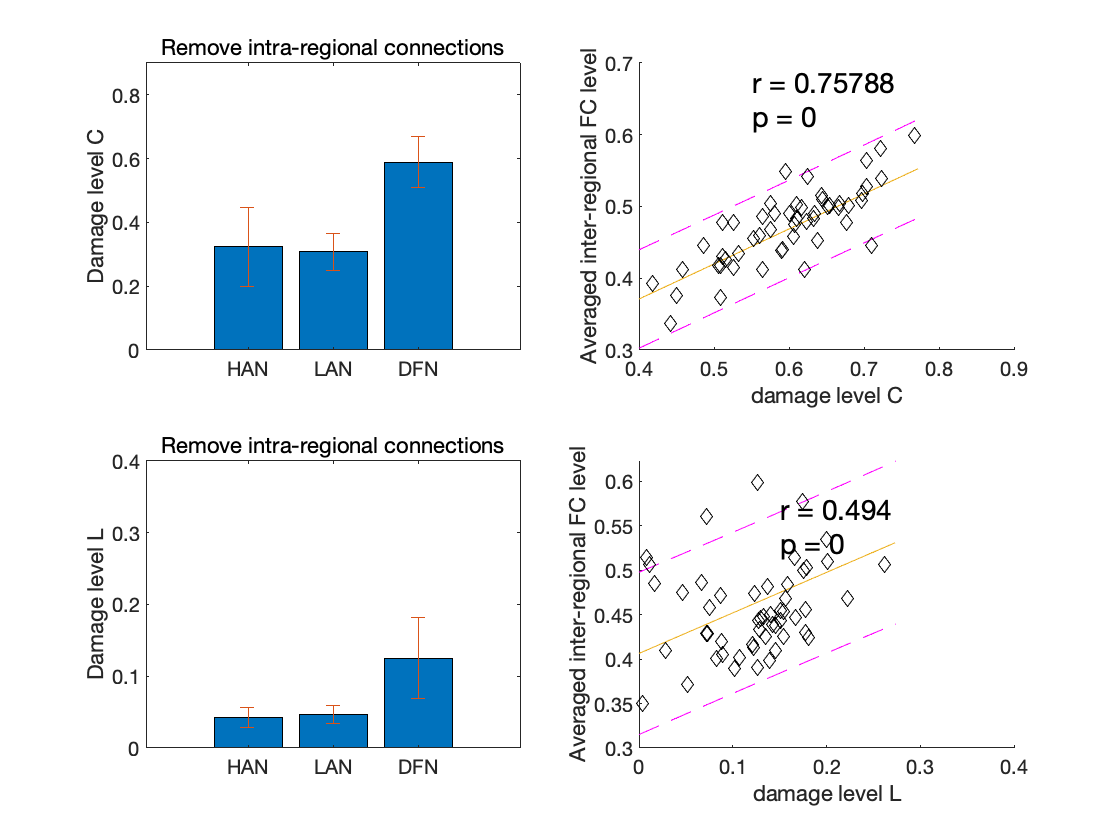



subplot(2, 2, 4)
r = corrcoef(1 - activity_inter(3, :), data(3, :));
h = plot_scatter(data(3, :), 1 - activity_inter(3, :));
xlim([0 0.4])
ylabel('Averaged inter-regional FC level')
xlabel('damage level L')
[H, P, CI, STATS] = ttest2(1 - activity_inter(3, :), data(3, :));
text(0.15, 0.55, {['r = ', num2str(r(1, 2))], ['p = ', num2str(P)]}, "FontSize", 14)

function h = plot_scatter(X, Y)

[X, I] = sort(X);
Y = Y(I);

[p, s] = polyfit(X, Y, 1);
x = 0:0.002:max(X);
y = polyval(p, x);
[y_fit,delta] = polyval(p,x,s);
ind = crossvalind('kfold', 314, 6);

hold on
h = plot(x,y_fit+2*delta,'m--',x,y_fit-2*delta,'m--');
%scatter(X, Y)
plot(x, y)
plot(X(ind == 1), Y(ind == 1), 'd', 'Color', 'black')
hold off
end

function data = threshold_net(data, p, thr_type, net_type)
% threshold 2D or 3D network
% Input:
%           data: inputed network
%           p: weight
%           thr_type: "Mix" keep half the strongest and weakest connections
%                     "low" keep the weakest connections.
%                     "high" keep the strongest connections.
%           net_type: "binary" converted to binarized network
% Output:
%           data: thresholded network


for i = 1:size(data, 3)
    
    net_win = data(:, :, i);
    net_win = tril(net_win);
    n = size(net_win, 1);                                %number of nodes
    net_win(1:n+1:end) = 0;                             %clear diagonal
    ind = find(net_win);                                %find all links
    E = sortrows([ind net_win(ind)], -2, "descend");               %sort by magnitude
    E = E(1:end, :);
    en = round((n ^ 2 - n) * (p / 2));                                 %number of links to be preserved
    
    if rem(en, 2) && isequal(net_win, net_win.')              %if symmetric matrix
        en = en + 1;                                         %ensure symmetry is preserved
    end
    
    % select links according to network mode
    if thr_type == "mix"
        
        E = E(en / 2 + 1: end - en / 2, 1);
        
    elseif thr_type == "low"
        
        E = E(1: end - en, 1);
        
    elseif thr_type == "high"
        
        E = E(en + 1:end, 1);
        
    end
    
    
    net_win(E) = 0;
    net_win = net_win + net_win';
    
    data(:, :, i) = net_win;
    
end

if net_type == "binary"
    
    data(data ~= 0) = 1;
    
end

end
